# Effect Size Estimate

We estimate the effect size for each electrode and each band by comparing the fraction of tests with a p-value less than 0.05 in the data set to simulated data sets with known effect sizes. 

This makes many assumptions and should only be interpreted as a very coarse estimate.

Schielke & Krekelberg  - 2022

## Define the ttest

Assume that each test of significance used a unequal samples, equal variance, two-tailed, t-test at alpha=0.05. 

Define a function `test`that, given the N for each of the groups and a simulated `effect` size, returns whether the null hypothesis could be rejected for `nrMonteCarlo` simulated data sets.

alpha = 0.05;
test = @(n1,n2,effect,nrMonteCarlo) (ttest2(randn(n1,nrMonteCarlo),randn(n2,nrMonteCarlo)+effect,'Alpha',alpha,'tail','both','vartype','equal'));

For example, simulate an effect of 0 with 20 controls, and 22 in the schizophrenia group. Because the true effect size in this simulation is zero, each` H==1 `is a false positive. So we expect` mean(H)` to be close to the significance level `alpha`. 

nrMonteCarlo = 5000;
H = test(20,22,0,nrMonteCarlo);
pFalsePositive = mean(H)

pFalsePositive = 0.0502

## Example Effect Size Estimate

Let's pretend that each of the 15 studies provided exactly one test  for a given electrode/band and that the observed fraction of significant tests (`fractionSignificantData`) was 0.5. 

% Extract the number of control/sz participants for each of the studies
N =num2cell([[ssvepTable.participants.control.n{:}]',[ssvepTable.participants.sz.n{:}]'],2);
nrMonteCarlo = 1000;
effectSizeSimulated =0:0.05:2;
nrEffectSize= numel(effectSizeSimulated);
fractionSignificantSimulated = nan(nrEffectSize,1);
for i=1:nrEffectSize
    fun = @(x) test(x(1),x(2),effectSizeSimulated(i),nrMonteCarlo);
    thisH = cellfun(fun,N,'uni',false);
    thisH = cat(1,thisH{:}); % [nrStudies nrMonteCarlo]
    fractionSignificantSimulated(i) = mean(mean(thisH,1),2);% Average over studies then over MC simulations
end

The fractionSignificantSimulated vector shows the expected fraction of signficant tests for each simulated effect size (and assuming that each of the 15 studies contributed 1 test). 

figure(1);
clf
plot(effectSizeSimulated,fractionSignificantSimulated)
xlabel 'Effect Size (D)'
ylabel 'Fraction Significant'
title 'Estimating Effect Size'
hold on
% Estimate where the simulated fraction crosses the fraction in the data
fractionSignificantData = 0.5;
plot(xlim,fractionSignificantData*ones(1,2));
ix = find(fractionSignificantSimulated>fractionSignificantData,1,'first');
effectSizeEstimate = effectSizeSimulated(ix-1) % Conservative ; the one before

effectSizeEstimate = 0.6500

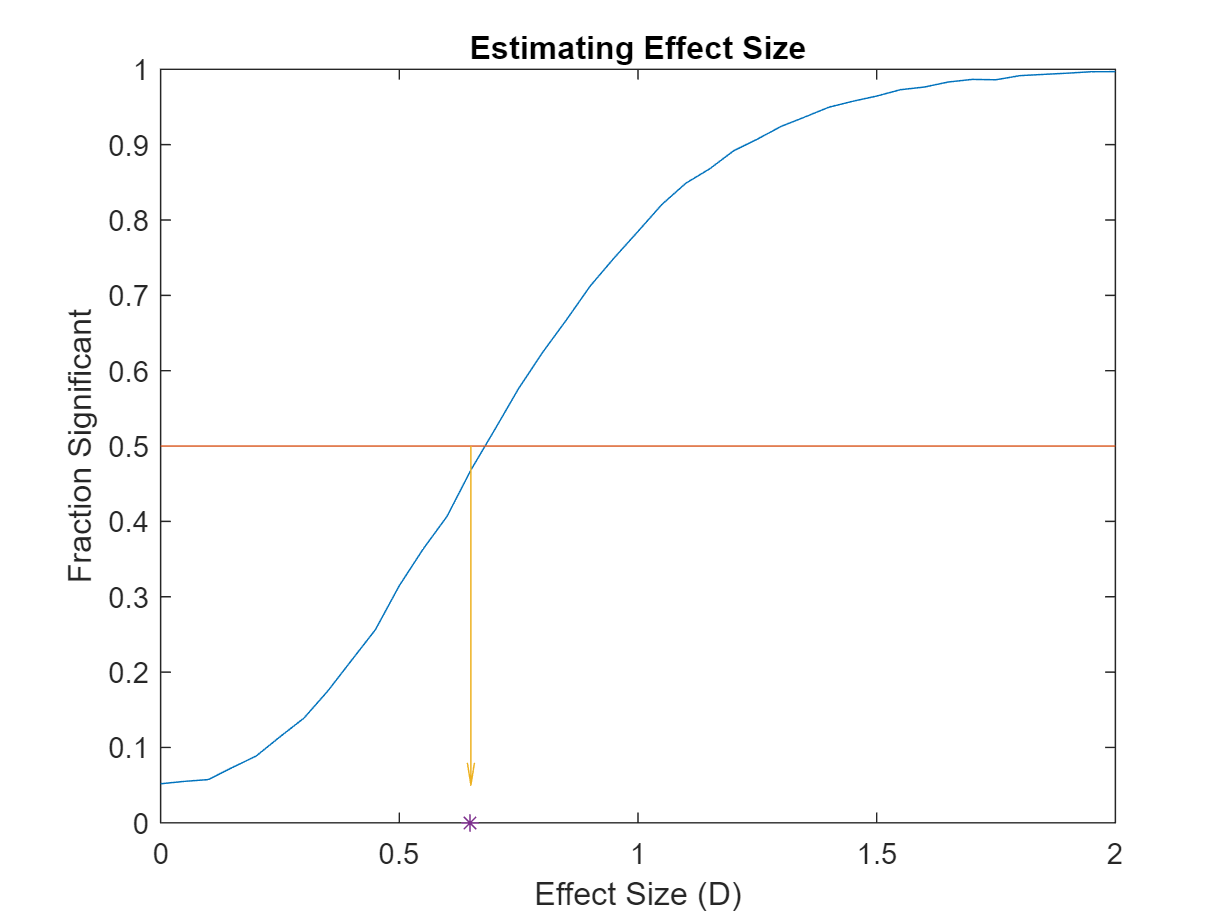

quiver(effectSizeEstimate,fractionSignificantData,0,-fractionSignificantData);
plot(effectSizeEstimate,0,'*'); % Show the estimate.

As expected, the fraction of significant tests increases with the simulated effect size. Based on these simulations, observing 50% significant tests out of the 15 studies requires an effect size of about 0.65. 

## Effect Size Estimates

In the data set, the number of tests (and the studies they came from, and therefore the N for the control and sz groups) differed across electrodes and bands. In this section we determine each of these numbers from the data, and then use the same logic as above to estimate the effect size from the fraction of significant tests. 

% Preliminaries to extract the data and band/electrode names.
setupElectrodes;
ssvepTable = reviewData;
resultMain= analyzeData(ssvepTable);
frequencyBands = fieldnames(ssvepTable.results);
nrFrequencyBands = numel(frequencyBands);
nrElectrodes = numel(keepElectrodes);
% Define simulation parameters
nrMonteCarlo = 1000;
effectSizeSimulated =0:0.05:2;
nrEffectSize= numel(effectSizeSimulated);
% Initialize the estimates with NaN. Any electrode/band combination for
% which there are no tests will stay NaN.
effectSizeEstimate = nan(nrFrequencyBands,nrElectrodes);
for f= 1:nrFrequencyBands
    for e= 1:nrElectrodes
        % Extract the relevant data from the resultMain struct
        thisData = resultMain.(frequencyBands{f}).(keepElectrodes{e});  
        if thisData.nrTTest >0 
            % If the data set included tests at this electrode/band, then
            % estimate the effect size            
            N = num2cell(thisData.N,2); % Put N in cell form (to use cellfun), with each row a test 
            fractionSignificantData = mean(thisData.sig<=alpha);
            if fractionSignificantData >0
                % If at least one was significant then we can try to
                % estimate the effect size
                for i=1:nrEffectSize
                    % Simulate effect sizes
                    fun = @(x) test(x(1),x(2),effectSizeSimulated(i),nrMonteCarlo);
                    thisH = cellfun(fun,N,'uni',false);
                    thisH = cat(1,thisH{:}); % [nrStudies nrMonteCarlo]
                    fractionSignificantSimulated = mean(mean(thisH,1),2);% Average over studies then over MC simulations
                    if fractionSignificantSimulated>fractionSignificantData
                        % Crossed the fractionSignificantData; use previous
                        % effectSize as the (conservative) estimate.
                        effectSizeEstimate(f,e) = effectSizeSimulated(i-1);
                        break; % No need to look at larger effects
                    end
                end
            else
                % No test was significant. Best conservative effect size estimate
                % =0.               
                effectSizeEstimate(f,e)  =0;
            end
        end
    end
end

We show the results for each band as a bar graph. There isn't much structure, suggestign that the effect sizes are relatively constant (at least as far as this rough estimation allows us to conclude). The mean across electrodes where there is at least some evidence that there is an effect (i.e., at least some tests are significant) is nearly 0.5 (Cohen's D). This is typically considered a medium effect size.

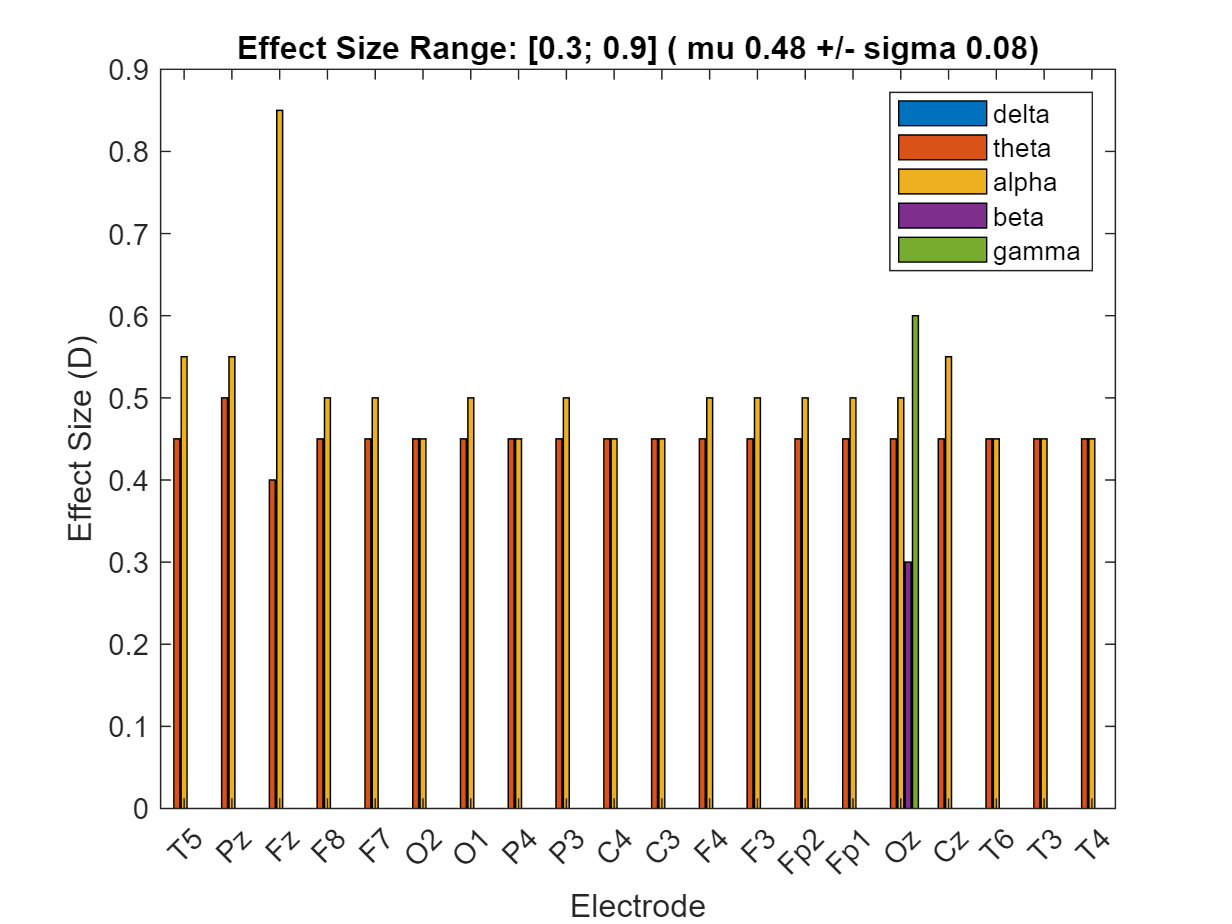

clf
bar(1:nrElectrodes,effectSizeEstimate')
set(gca,'Xtick',1:nrElectrodes,'XTickLabel',electrodeSelection);
ylabel 'Effect Size (D)'
xlabel 'Electrode'
legend(frequencyBands)
range = [min(effectSizeEstimate(effectSizeEstimate>0)) max(effectSizeEstimate(effectSizeEstimate>0))];
title(sprintf('Effect Size Range: [%.1f; %.1f] ( mu %.2f +/- sigma %.2f)',range(1),range(2),mean(effectSizeEstimate(effectSizeEstimate>0),"omitnan"),std(effectSizeEstimate(effectSizeEstimate>0),0,'omitnan')))